# **Vectorial KL-expansions with mortality data**

In this live script, we demonstrate a numerical method for vectorial KL-expansions on mortality rate data. Specifically, we use the integral methed described in *Karhunen-Loeve Expansions and their Applications *by Limin Wang.

**Fredholm integral equation**

The eigenfunctions and eigenvalues should approximately solve


$$\int_{0}^{1}  \left[\matrix{ Cov(X_1(t),X_1(s)) & \cdots & Cov(X_d(t),X_1(s)) \cr \vdots & & \vdots  \cr Cov(X_d(t),X_1(s)) & \cdots & Cov(X_d(t),X_d(s))  }\right]\left[\matrix{f^{(1)}(s) \cr \vdots \cr f^{(d)}(s) }\right]ds = \lambda \left[\matrix{f^{(1)}(t) \cr \vdots \cr f^{(d)}(t) }\right]ds$$


**Integral method**

Assuming the domain $t \in [0,1]$ with $n$ equally spaced evaluation points, the integral of a function $g$ can be approximated by

$\int_{0}^{1}g(t)dt \approx \frac{1}{n}\sum_{i=0}^{n-1}g(t_i)$.

Using these $1/n$ weights adheres to what Wang calls the *uniform *scheme. It can be shown that the application of this scheme on approximating solutions to the Fredholm integral equation amounts to solving the symmetric eigvenvalue problem

$W^{1/2}KW^{1/2}\phi = \phi \Lambda$, with

$K = \left[\matrix{Cov(X_1,X_1^T) & \cdots & Cov(X_1,X_d^T) \cr \vdots & \ddots & \vdots \cr Cov(X_d,X_1^T) & \cdots & Cov(X_d,X_d^T)}\right]$, $\Lambda = \left[\matrix{\lambda_1 & 0 & \cdots & 0 \cr 0 & \lambda_2 & \cdots & 0 \cr \vdots & \vdots  & 0 & \cdots \lambda_{nd}}\right]$

and $W$ an $nd \times nd$ diagonal matrix of weights $1/n$. Above, $Cov(X_i,X_j^T)$ is an $n \times n$ auto-covariance matrix evaluated at pairs of $t_i$ and $t_j$. Then the eigenfunctions are recovered by $W^{-1/2}\phi$.

**Mortality rates data **

load Data\mortality_rates_array.mat

**Compute covariance K and correlation C**

K = covariance_function(mortality_rates_array); % K(i,j,k,l) = Cov(V_k(i),V_l(j))
C = correlation_function(mortality_rates_array); % C(i,j,k,l) = Cor(V_k(i),V_l(j))

**Compute eigenvalues and eigenfunctions for vectorial setting**

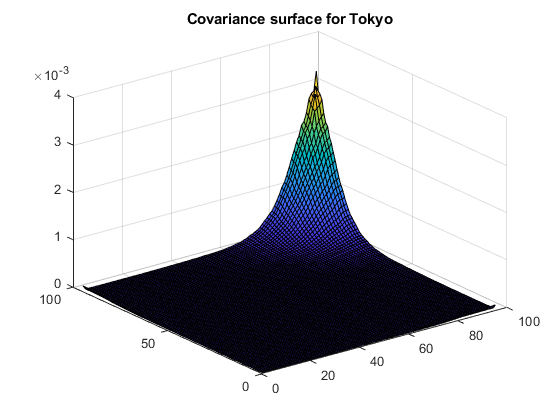

[f,lambda] = KL(K);

surf(K(:,:,41,41))
title("Covariance surface for Tokyo")

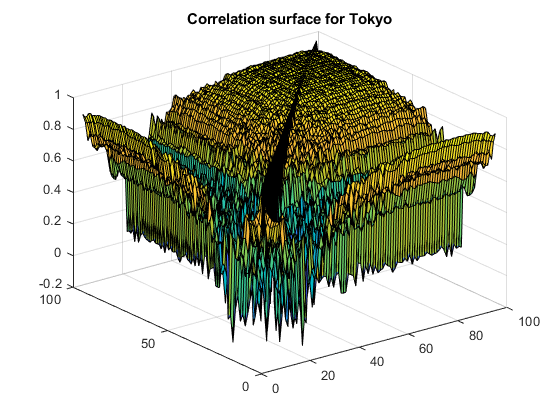


surf(C(:,:,41,41))
title("Correlation surface for Tokyo")

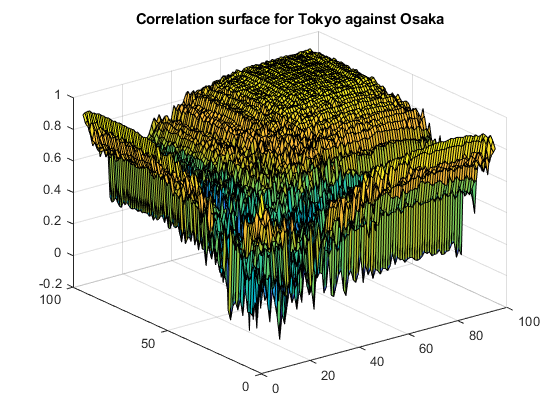


surf(C(:,:,41,33))
title("Correlation surface for Tokyo against Osaka")

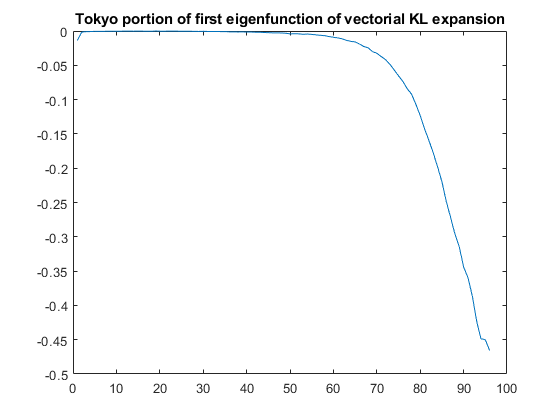


plot(f((40*96+1):41*96,1))
title("Tokyo portion of first eigenfunction of vectorial KL expansion")

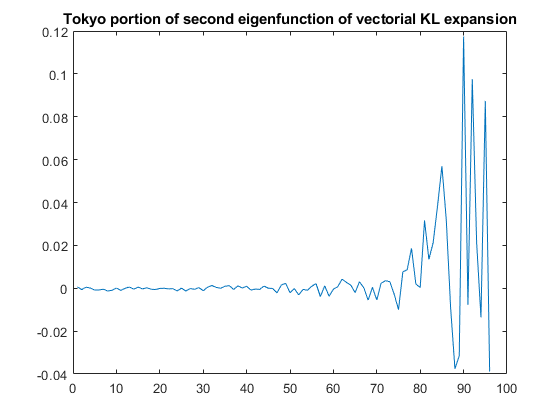


plot(f((40*96+1):41*96,2))
title("Tokyo portion of second eigenfunction of vectorial KL expansion")

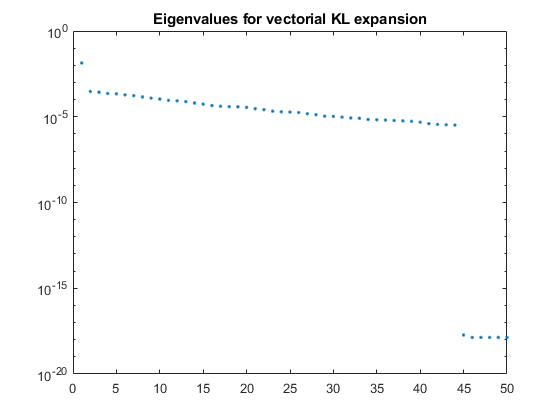


semilogy(lambda(1:50),".")
title("Eigenvalues for vectorial KL expansion")

**Compute eigenvalues and eigenfunctions for univariate setting**

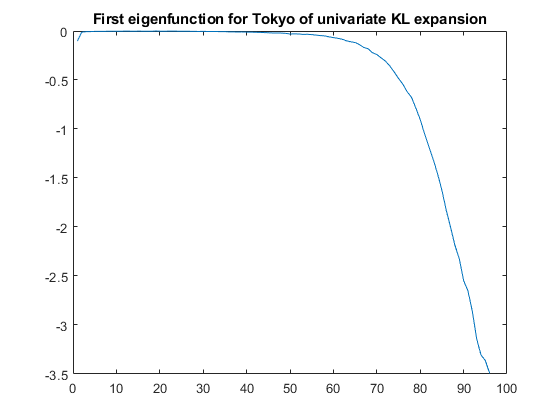

n_prefectures = 47;
n_evaluation_points = 96;

univariate_lambdas = zeros(n_evaluation_points);
univariate_f = zeros(n_evaluation_points,n_evaluation_points,n_prefectures);


for j = 1:n_prefectures
    [univariate_f(:,:,j),univariate_lambdas(j,:)] = KL(K(:,:,j,j));
end

plot(univariate_f(1:96,1,41))
title("First eigenfunction for Tokyo of univariate KL expansion")

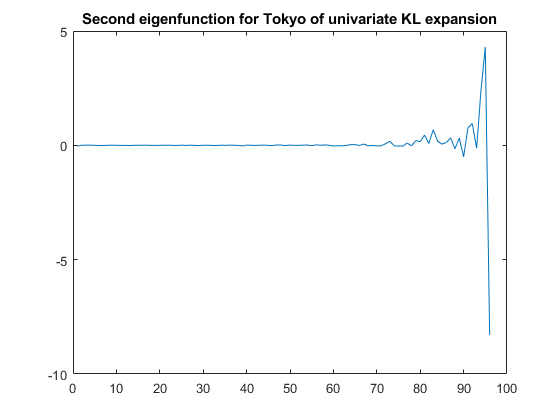


plot(univariate_f(1:96,2,41))
title("Second eigenfunction for Tokyo of univariate KL expansion")

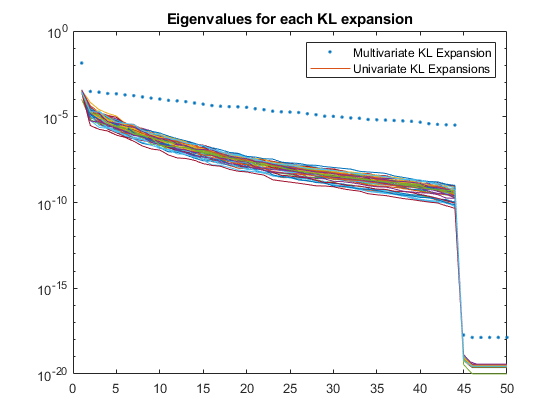


semilogy(lambda(1:50),".")
title("Eigenvalues for each KL expansion")
hold on
semilogy(univariate_lambdas(:,1:50)')
legend("Multivariate KL Expansion","Univariate KL Expansions")

function [K] = covariance_function(data_array)
% -data_array should be a T x d x n array where T is the number of
% evaluation points, d is the dimension of each vectorial observation, and
% n is the replication 
% -outputs an an T x T x d x d array whose (i,j,k,l) entry is Cov(V_k(i),V_j(l))

[T,d,n] = size(data_array);

% compute sample mean function of each dimension
data_means = mean(data_array,3); % jth column is the mean function of the jth dimension
centered_data = data_array-data_means; % subtracts mean function from each observation

% compute n x n x d x d covariance matrix
K = zeros(T,T,d,d);

for j1 = 1:d
    for j2 = 1:d 
            K(:,:,j1,j2) = (1/n)*(squeeze(centered_data(:,j1,:)))*(squeeze(centered_data(:,j2,:)))';
    end
end


end


function [C] = correlation_function(data_array)
% -data_array should be a T x d x n array where T is the number of
% evaluation points, d is the dimension of each vectorial observation, and
% n is the replication 
% -outputs an an T x T x d x d array whose (i,j,k,l) entry is Cov(V_k(i),V_j(l))

[T,d,n] = size(data_array);

% compute sample mean function of each dimension
data_means = mean(data_array,3); % jth column is the mean function of the jth dimension
centered_data = data_array-data_means; % subtracts mean function from each observation

% compute n x n x d x d covariance matrix
C = zeros(T,T,d,d);

for j1 = 1:d
    for j2 = 1:d 
            centered_j1_data = (squeeze(centered_data(:,j1,:)));
            centered_j2_data = (squeeze(centered_data(:,j2,:)));
            C(:,:,j1,j2) = (1/n)*(centered_j1_data./std(centered_j1_data')')*((centered_j2_data)./std(centered_j2_data')')';
    end
end


end



%%% KL-expansion function
function [eigenfunctions,eigenvalues] = KL(K_array)
% K should be an n x n x d x d covariance array whose (i,j,k,l) entry is Cov(V_k(i),V_j(l))

[T,~,d,~] = size(K_array) ;

% convert K_array into nd x nd covariance matrix
K = zeros(T*d);

for j1 = 1:d
    for j2 = 1:d
            row_indices = ((j1-1)*T+1):(j1*T);
            column_indices = ((j2-1)*T+1):(j2*T);         
            K(row_indices,column_indices) = K_array(:,:,j1,j2);
    end
end

% compute eigenfunctions and eigenvalues
sqrtW = 1/sqrt(T)*diag(ones(T*d,1));
invsqrtW = sqrt(T)*diag(ones(T*d,1));

X = sqrtW*K*sqrtW;
[U,S,V] = svd(X);

eigenfunctions = invsqrtW*V;
eigenvalues = diag(S);



end